arduino = [-0.50, -109.86; -0.48, -103.22; -0.46, -98.76; -0.44, -89.96; -0.42, -85.44; -0.40, -75.33; -0.38, -68.27; -0.36, -63.15; -0.34, -54.17; -0.32, -47.33; -0.30, -39.81; -0.28, -35.46; -0.26, -23.48; -0.24, -18.82; -0.22, -11.69; -0.20, -0.00; -0.18, -0.00; -0.16, 0.00; -0.14, 0.00; -0.12, 0.00; -0.10, -0.00; -0.08, 0.00; -0.06, 0.00; -0.04, 0.00; -0.02, 0.00; 0.00, 0.00; 0.02, -0.00; 0.04, 0.00; 0.06, 0.00; 0.08, 0.00; 0.10, 0.00; 0.12, 0.00; 0.14, 0.00; 0.16, 0.00; 0.18, 0.00; 0.20, 0.00; 0.22, 0.05; 0.24, 14.07; 0.26, 21.00; 0.28, 30.58; 0.30, 41.51; 0.32, 42.40; 0.34, 56.13; 0.36, 64.34; 0.38, 71.63; 0.40, 82.31; 0.42, 103.83; 0.44, 94.74; 0.46, 101.75; 0.48, 113.60; 
]

arduino =    -0.5000 -109.8600
   -0.4800 -103.2200
   -0.4600  -98.7600
   -0.4400  -89.9600
   -0.4200  -85.4400
   -0.4000  -75.3300
   -0.3800  -68.2700
   -0.3600  -63.1500
   -0.3400  -54.1700
   -0.3200  -47.3300


current = [-0.16 -0.15 -0.15 -0.15 -0.15 -0.15 -0.14 -0.14 -0.14 -0.14 -0.13 -0.13 -0.13 -0.13 -0.12 -0.14 -0.1 -0.08 -0.06 -0.04 -0.03 -0.02 -0.01 0.00 0 0 0 0 0 0.01 0.03 0.04 0.06 0.07 0.1 0.13 0.15 0.14 0.14 0.14 0.14 0.14 0.14 0.14 0.15 0.15 0.15 0.15 0.15 0.15 ]'

current =    -0.1600
   -0.1500
   -0.1500
   -0.1500
   -0.1500
   -0.1500
   -0.1400
   -0.1400
   -0.1400
   -0.1400


dutycycle = arduino(:,1)

dutycycle =    -0.5000
   -0.4800
   -0.4600
   -0.4400
   -0.4200
   -0.4000
   -0.3800
   -0.3600
   -0.3400
   -0.3200


speed = arduino(:,2)

speed =  -109.8600
 -103.2200
  -98.7600
  -89.9600
  -85.4400
  -75.3300
  -68.2700
  -63.1500
  -54.1700
  -47.3300


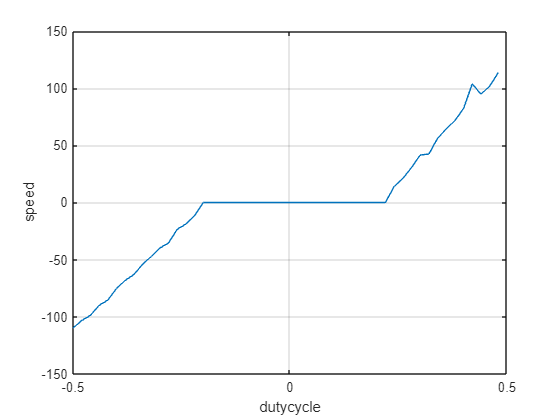


figure;
plot(dutycycle, speed);
grid on;
xlabel("dutycycle")
ylabel("speed")

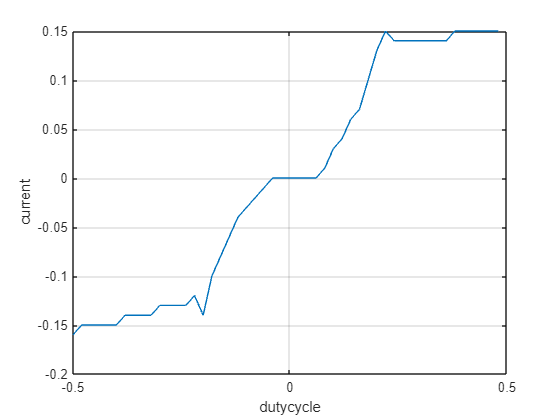


figure;
plot(dutycycle, current);
grid on;
xlabel("dutycycle")
ylabel("current")

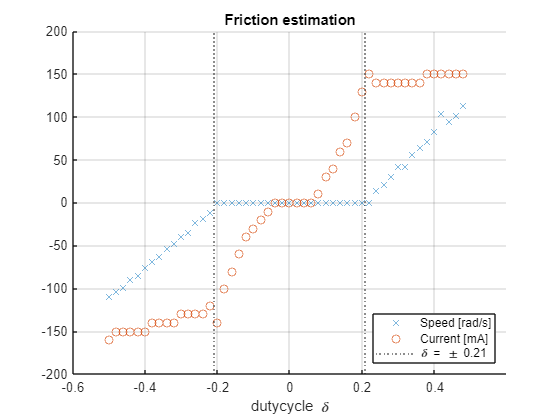


figure;
hold on;
plot(dutycycle, speed, 'x');
plot(dutycycle, current*1000, 'o');
xline([0.21, -0.21], ':')
grid on;
xlabel("dutycycle \delta"); 
xlim([-0.6, 0.6]); ylim([-200, 200])
legend("Speed [rad/s]", "Current [mA]", "\delta = \pm 0.21", '', "location", "southeast")
title("Friction estimation")

save("friction.mat", "dutycycle", "speed", "current")

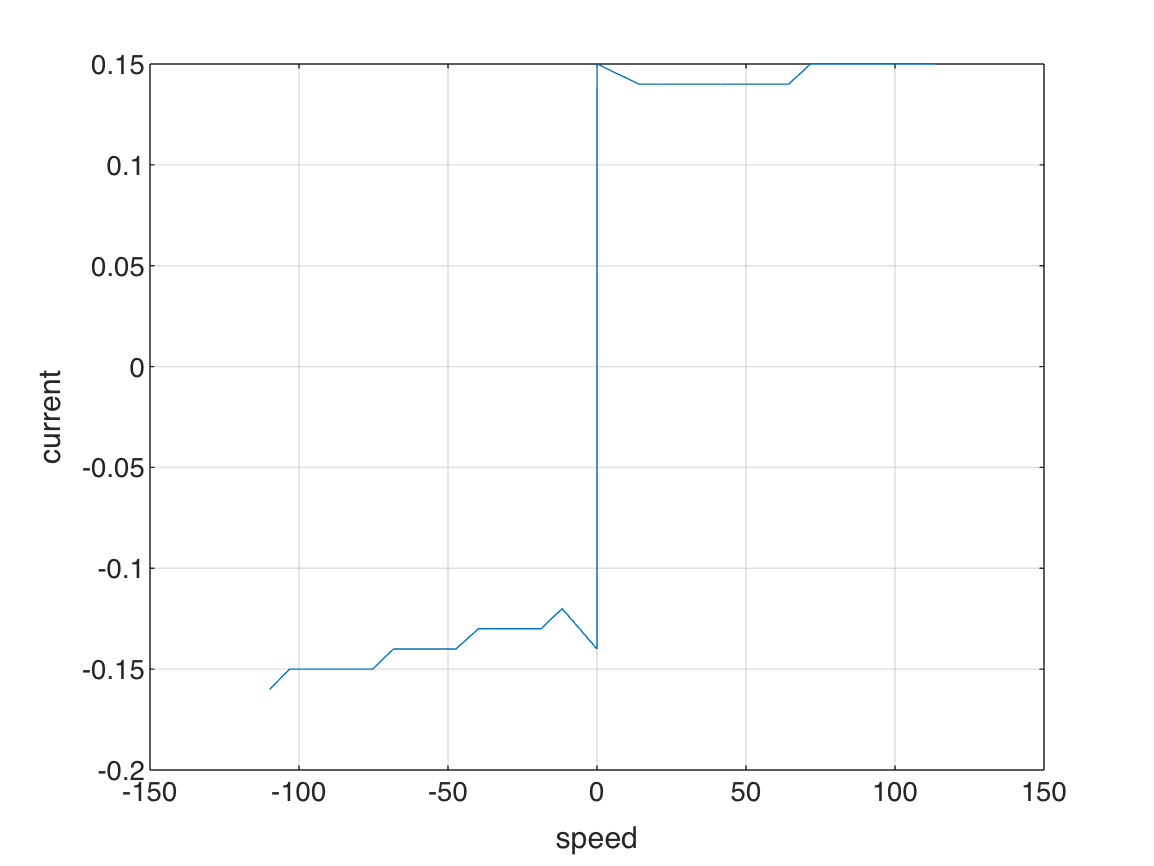

load friction.mat

figure;
plot(speed, current)
grid on;
xlabel("speed"); ylabel("current")

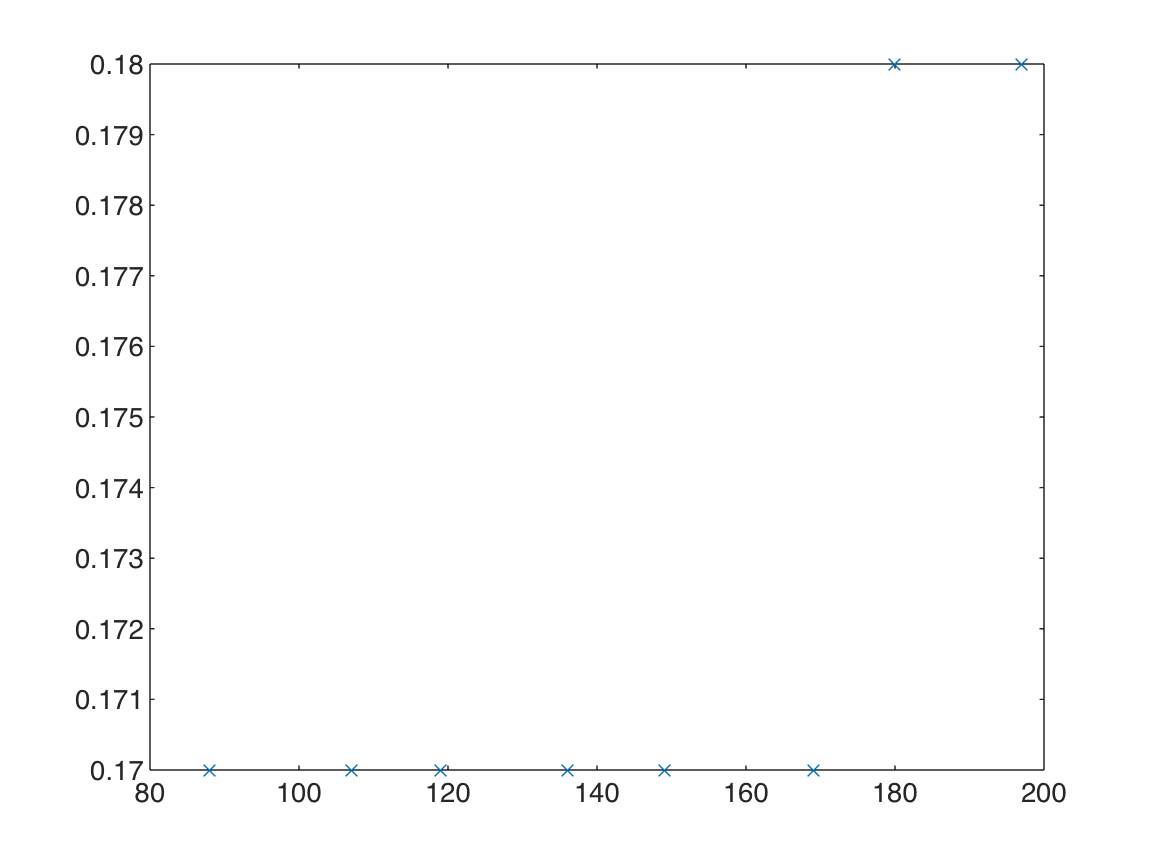


load voltage_current_speed.mat;
figure;
plot(w, I, 'x')

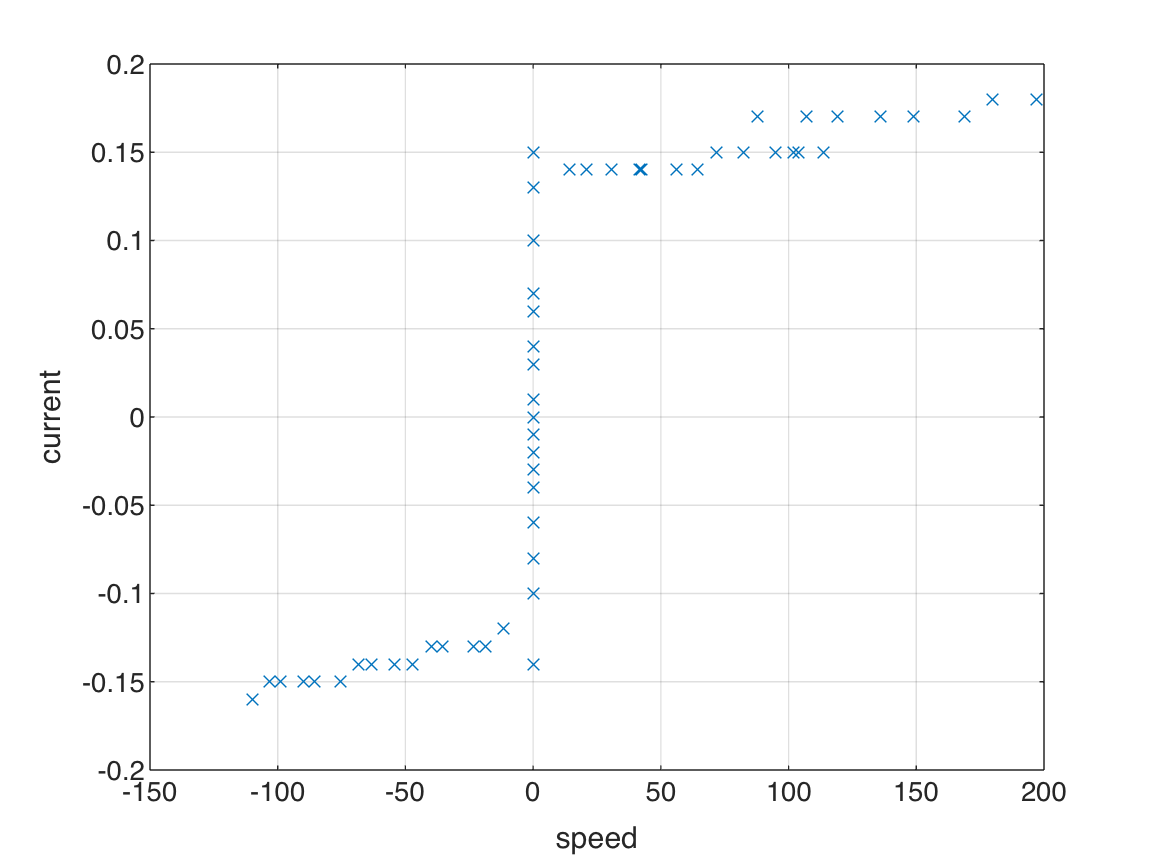


% Merge the two datasets
speed = [speed; w]
current = [current; I]

figure;
plot(speed, current, 'x')
grid on;
xlabel("speed"); ylabel("current")

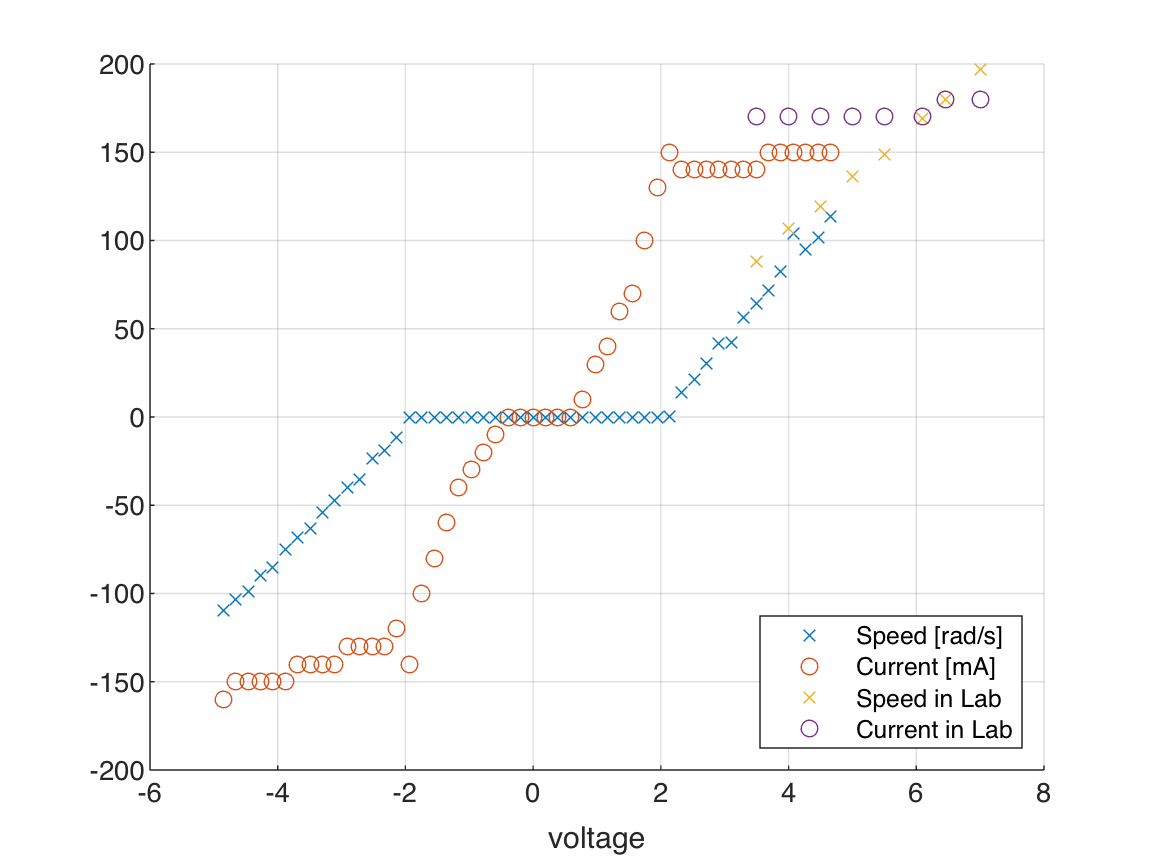


V_pwm = dutycycle * 9.7
voltage = [V_pwm; V]
figure;
hold on;
plot(voltage, speed, 'x');
plot(voltage, current*1000, 'o')
plot(V, w, 'x')
plot(V, I*1000, 'o')
grid on;
xlabel('voltage')
legend("Speed [rad/s]", "Current [mA]", "Speed in Lab", "Current in Lab", "location", "southeast")

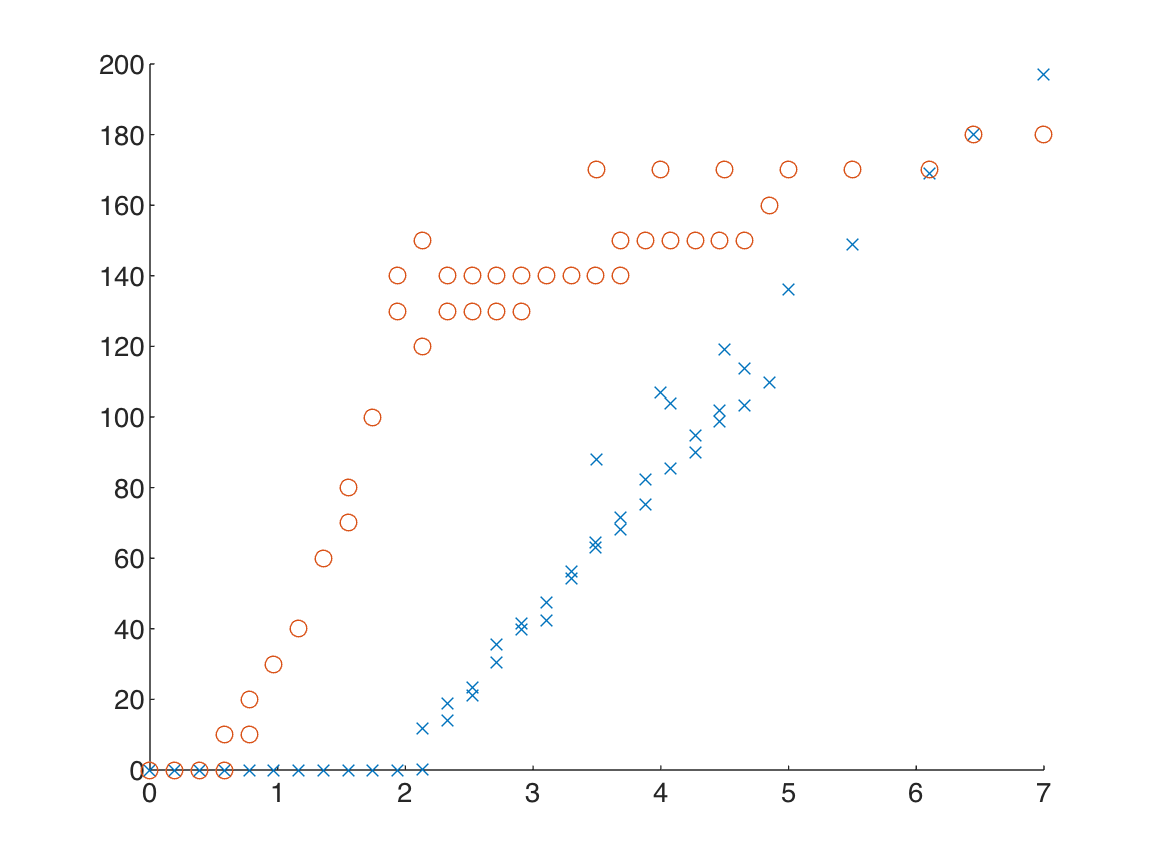

voltage_abs = abs(voltage)


speed_abs = abs(speed)
current_abs = abs(current)

figure;
hold on;
plot(voltage_abs, speed_abs, 'x')
plot(voltage_abs, current_abs*1000, 'o')

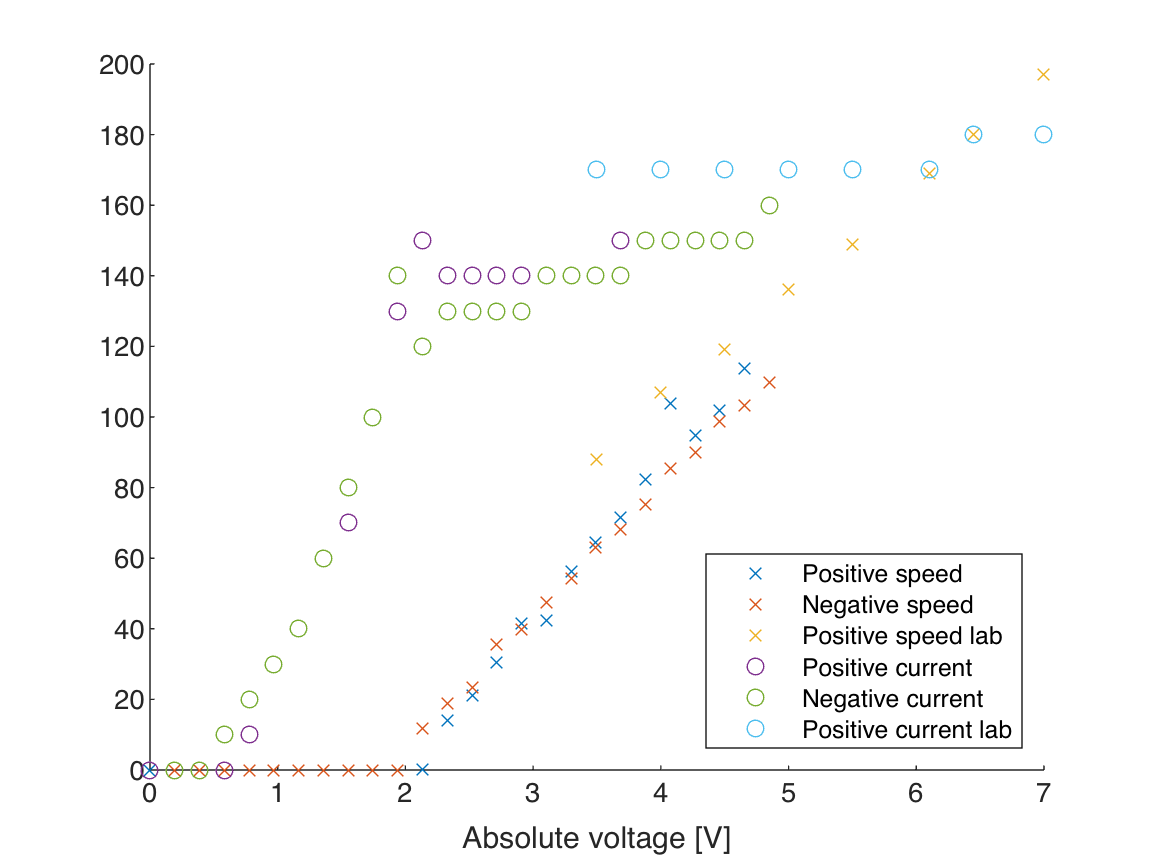


pos_indexes = find(voltage >= 0);
neg_indexes = find(voltage < 0);

figure; hold on;
plot(voltage(pos_indexes), speed(pos_indexes), 'x');
plot(abs(voltage(neg_indexes)), abs(speed(neg_indexes)), 'x')
plot(V, w, 'x')
plot(voltage(pos_indexes), 1000*current(pos_indexes), 'o');
plot(abs(voltage(neg_indexes)), abs(1000*current(neg_indexes)), 'o')
plot(V, 1000*I, 'o')
xlabel("Absolute voltage [V]")
legend("Positive speed", "Negative speed", "Positive speed lab", "Positive current", "Negative current", "Positive current lab", "location", "southeast")

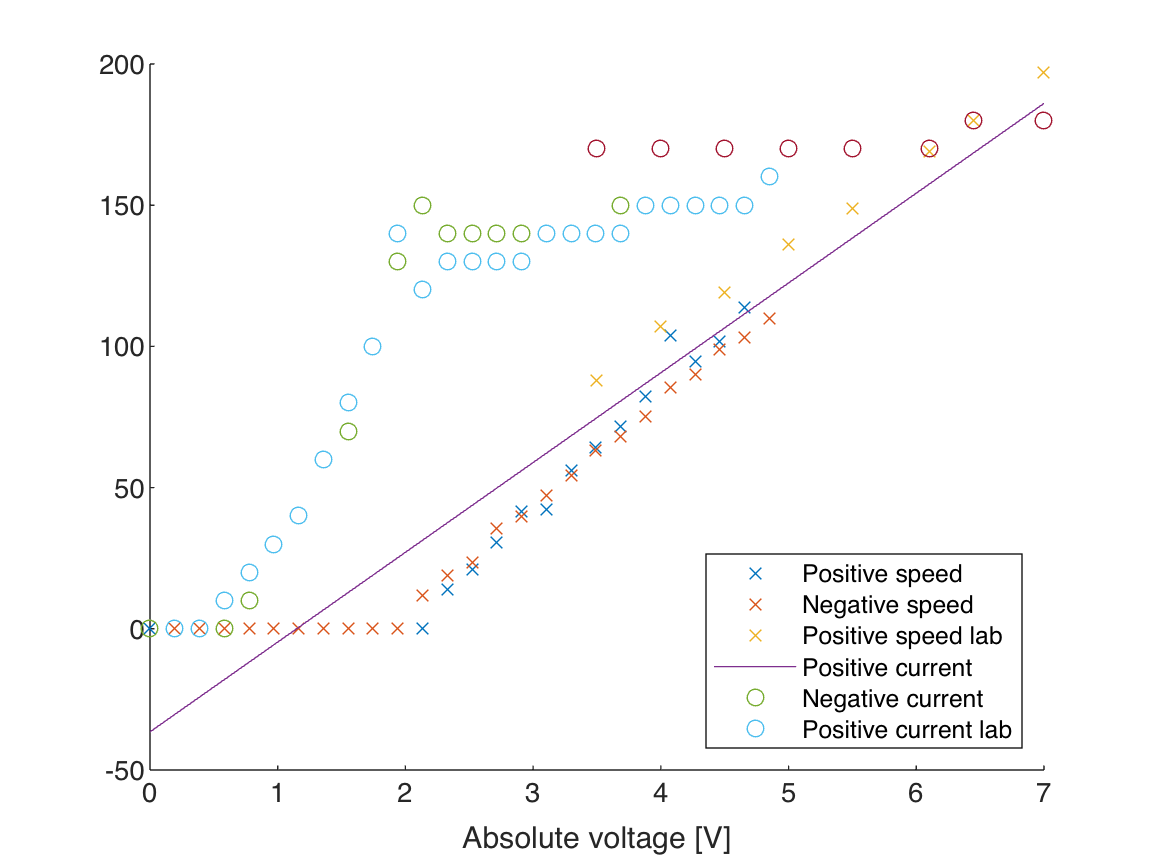

x = [voltage(pos_indexes), ones(length(voltage(pos_indexes)), 1)]
y = speed(pos_indexes);

theta = x\ y
figure; hold on;
plot(voltage(pos_indexes), speed(pos_indexes), 'x');
plot(abs(voltage(neg_indexes)), abs(speed(neg_indexes)), 'x')
plot(V, w, 'x')
plot(voltage(pos_indexes), x*theta)
plot(voltage(pos_indexes), 1000*current(pos_indexes), 'o');
plot(abs(voltage(neg_indexes)), abs(1000*current(neg_indexes)), 'o')
plot(V, 1000*I, 'o')
xlabel("Absolute voltage [V]")
legend("Positive speed", "Negative speed", "Positive speed lab", "Positive current", "Negative current", "Positive current lab", "location", "southeast")